# 3.1 Um aluno do primeiro ano de um curso de Engenharia tem todas as semanas 2 aulas Teorico-Praticas de uma Unidade Curricular X as 9:00, as quartas e sextas. Todos os dias que tem aulas desta UC, o aluno decide se vai a aula ou nao da seguinte forma: Se tiver estado presente na aula anterior a probabilidade de ir a aula e 70%; se faltou a anterior, a probabilidade de ir e 80%.

## a) Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

%Todas as semanas tem 2 aulas TPs da UCx às 9h00 quarta e sexta
%1 - nao ir a aula
%2 - ir a aula
Tij = [0.2 0.3
       0.8 0.7];
   
sum(Tij); % se der vetor de 1 temos matriz estocastica

x0 = [0 1]';

%x2 = Tijx1 = Tij(Tijx0) = Tij2x0
x2 = Tij^2*x0;
fprintf('1a) reposta = %f\n', x2(2));

1a) reposta = 0.730000


## (b) Se nao estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

x0 = [1 0]'; %nao estar presente na 1ª e esta na 2ª

%x2 = Tijx1 = Tij(Tijx0) = Tij2x0
x2 = Tij^2*x0;
fprintf('1b) reposta = %f\n', x2(2));

1b) reposta = 0.720000


## c) Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na ultima aula, assumindo que o semestre tem exactamente 15 semanas de aulas e nao existem feriados?

x0 = [0 1]'; %nao estar presente na 1ª e esta na 2ª
x2 = Tij^29*x0;
fprintf('1c) reposta = %f\n', x2(2));

1c) reposta = 0.727273


## d) Represente num grafico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula e de 85%.

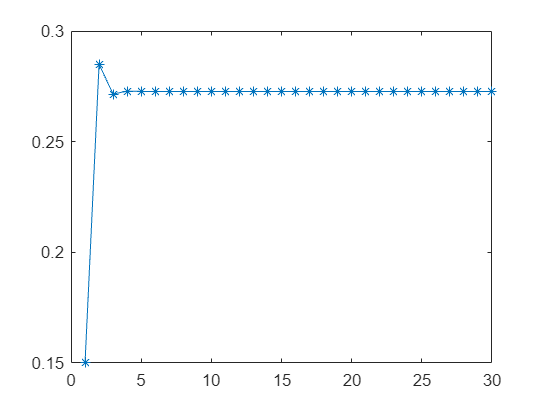

v = [0.15 0.85]';
res = zeros(1, 30);
res(1) = 0.15;
for i = 2:30
    v = Tij * v;
    %v2 = Tij^2 * v;
    res(i) = v(1);
end
plot(res, '*-');